# Example 3: Complex geometry with the von Karman spectrum

 The wind field is now simulated on a circle defined in the vertical plane  (yz) normal to the flow. The function windSim is used with two input files:

-  'windData_Example3.txt' , which  includes information about the wind field only.

-  'circle.txt', which is a file with two columns, where the first one contains the coordinates of the nodes along axis y, and the second columns contains the coordinates of the nodes along axis z.

 The von Karman model has been used with the turbulence length scale Lu, Lv and Lw estimated assuming that the assumption of local isotropy applies. These length scale are, therefore, proportional to the measurement height. This means also that the "modified" von Karman model can only be applied n the surface layer ( first 10 percent of the atnospheric boundary layer)  

## Time series simulation

clearvars;close all;clc;
rng(1)
windData = 'windData_Example3.txt';
myGeometry = 'circle.txt';
[u,v,w,t,nodes] = windSim(windData,'geometry',myGeometry);

Duration of target time series is 2.28 hours, i.e. 8.19e+03 sec 

Expected computation time: From 38 to 80 seconds 



u = u+nodes.U*ones(size(t)); % get fluctuating + mean value

## Display the geometry

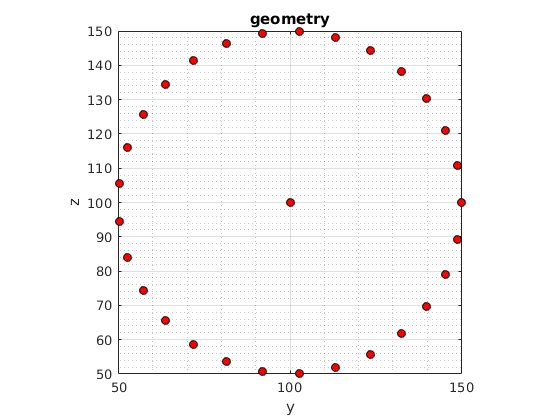

figure
plot(nodes.Y,nodes.Z,'ko','markerfaceColor','r')
ylabel('z')
xlabel('y')
title('geometry')
set(gcf,'color','w')
axis square 
grid on
grid minor

## Time series overview

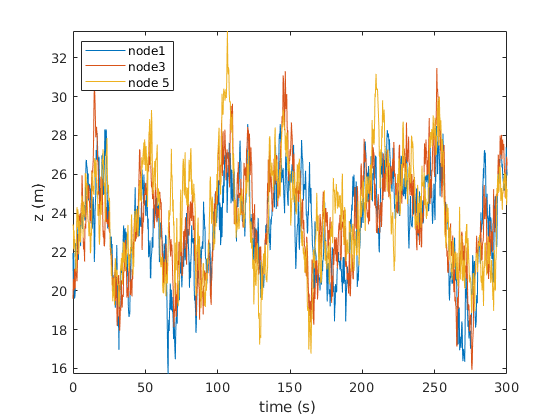

% ratios between specified in the file windData_Example3.txt
stdU = 2.6;
stdV = 2.2;
stdW = 1.6;
figure
box on; hold on
plot(t,u(1:2:6,:))
xlabel('time (s) ');
zlabel('u (m/s)')
ylabel('z (m)')
set(gcf,'color','w')
legend('node1','node3','node 5','location','best')
axis tight
xlim([0,300])

## Standard deviation of wind velocity fluctuations

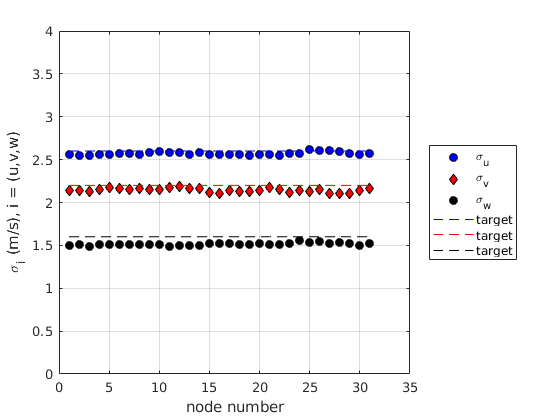

clf;close all;
figure
box on;hold on,grid on
plot(std(u,0,2),'ko','markerFaceColor','b')
plot(std(v,0,2),'kd','markerFaceColor','r')
plot(std(w,0,2),'ko','markerFaceColor','k')
plot([1:numel(nodes.Y)],stdU*ones(1,numel(nodes.Y)),'b--',...
    [1:numel(nodes.Y)],stdV*ones(1,numel(nodes.Y)),'r--',...
    [1:numel(nodes.Y)],stdW*ones(1,numel(nodes.Y)),'k--')
xlabel('node number')
ylabel('\sigma_{i} (m/s), i = (u,v,w)')
set(gcf,'color','w')
legend('\sigma_{u}','\sigma_{v}','\sigma_{w}',...
    'target','target','target','location','eastoutside')
ylim([0 4])

## Turbulence intensity

The present code specifies a turbulent intensity that decreases for increasing mean wind velocity, i.e. for increasing altitudes. This is more realistic than the constant turbulent intensity introduced in a previous version.

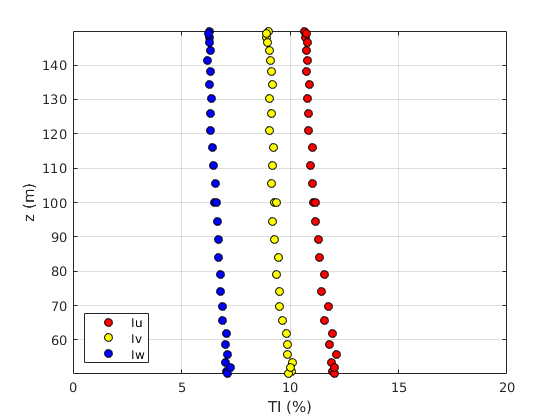

Iu = std(u,0,2)./nodes.U*100;
Iv = std(v,0,2)./nodes.U*100;
Iw = std(w,0,2)./nodes.U*100;

figure
box on;hold on,grid on
plot(Iu,nodes.Z,'ko','markerFaceColor','r')
plot(Iv,nodes.Z,'ko','markerFaceColor','y')
plot(Iw,nodes.Z,'ko','markerFaceColor','b')
ylabel('z (m)')
xlabel('TI (%)')
set(gcf,'color','w')
legend('Iu','Iv','Iw','location','SouthWest')
xlim([0 20])
ylim([min(nodes.Z) max(nodes.Z)])

## Comparison with the von Karman spectrum

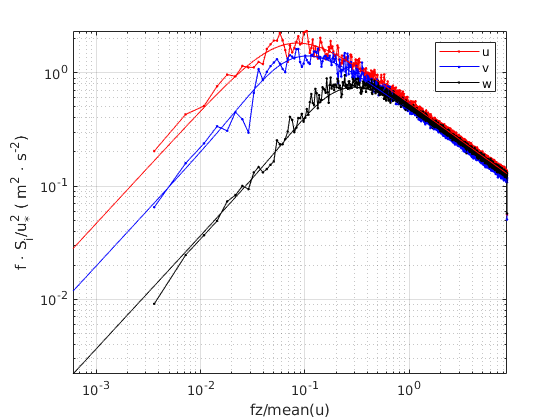

tmax = t(end);
fs = 1/median(diff(t));
% block duration (each)
tBlock = 1200;
% number of blocks
NBlock = round(tmax/tBlock);
% number of data point per block
Nfft = round(numel(t)/NBlock);
f1=logspace(log10(1/t(end)),log10(fs/2),100)';
clear Su* Sv* Sw*

Lu	=       170;	
Lv	=	100;							
Lw	=	35;

for ii=1:numel(nodes.Z),
    [Su0(ii,:),f0]=pwelch(detrend(u(ii,:)),Nfft,round(Nfft/2),Nfft,fs);
    [Sv0(ii,:),f0]=pwelch(detrend(v(ii,:)),Nfft,round(Nfft/2),Nfft,fs);
    [Sw0(ii,:),f0]=pwelch(detrend(w(ii,:)),Nfft,round(Nfft/2),Nfft,fs);
    
    Su0(ii,:) = f0'.*Su0(ii,:)./(var(u(ii,:)));
    Sv0(ii,:) = f0'.*Sv0(ii,:)./(var(v(ii,:)));
    Sw0(ii,:) = f0'.*Sw0(ii,:)./(var(w(ii,:)));

    [Su1(ii,:)] = VonKarmanSpectrum(f1,mean(u(ii,:)),Lu,'u'); % already normalized with the variance and frequency f
    [Sv1(ii,:)] = VonKarmanSpectrum(f1,mean(u(ii,:)),Lv,'v'); % already normalized with the variance and frequency f
    [Sw1(ii,:)] = VonKarmanSpectrum(f1,mean(u(ii,:)),Lw,'w'); % already normalized with the variance and frequency f
    
    
end

% average the single-point spectra
Su0 = mean(Su0); Sv0 = mean(Sv0); Sw0 = mean(Sw0); 
Su1 = mean(Su1); Sv1 = mean(Sv1); Sw1 = mean(Sw1); 

% plot the spectra
clf;close all;
figure
box on;hold on

h(1)= plot(f0.*mean(nodes.Z./nodes.U),Su0(:).*stdU.^2,'r.-');
h(2)= plot(f0.*mean(nodes.Z./nodes.U),Sv0(:).*stdV.^2,'b.-');
h(3)= plot(f0.*mean(nodes.Z./nodes.U),Sw0(:).*stdW.^2,'k.-');


plot(f1.*mean(nodes.Z./nodes.U),Su1(:).*stdU.^2,'r')
plot(f1.*mean(nodes.Z./nodes.U),Sv1(:).*stdV.^2,'b')
plot(f1.*mean(nodes.Z./nodes.U),Sw1(:).*stdW.^2,'k')
% plot([5 100],0.3*[5 100].^(-2/3),'g')
% plot([5 100],0.4*[5 100].^(-2/3),'m')
legend(h,'u','v','w')

xlabel(' fz/mean(u) ');
set(gca,'Xscale','log','Yscale','log')
ylabel('f \cdot S_{i}/u^2_* ( m^2 \cdot s^{-2})')
set(gcf,'color','w')
axis tight
grid on
grid minor

## Co-coherence

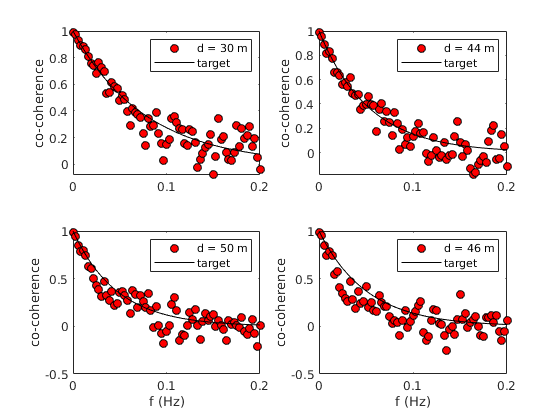

% time step & sampling frequency
dt = median(diff(t));
fs = 1/dt;
tmax = t(end);
f0 = 1/tmax;
[Nsamples,N] = size(u);
% block duration (each)
NBlock = 20;% number of blocks
% number of data point per block
Ncoh = round(N/NBlock);
clear Su Sv Sw

if mod(Ncoh,2)
    cocoh = zeros(10,10,round(Ncoh/2));
else
    cocoh = zeros(10,10,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function "coherence"
for ii=1:10
    for jj=1:10
        [cocoh(ii,jj,:),~,freq] = coherence(u(ii,:),u(jj,:),Ncoh,round(Ncoh/2),Ncoh,fs);
    end
end

dz = abs(nodes.Z-nodes.Z');
meanU_coh = 0.5*(nodes.U +nodes.U');
nodeTarget = [4 6 8 10];

figure
for ii=1:numel(nodeTarget)
    subplot(2,2,ii)
    box on;hold on
    plot(freq,squeeze(cocoh(1,nodeTarget(ii),:)),'ko','markerfacecolor','r');
    plot(freq,exp(-10.*dz(1,nodeTarget(ii)).*freq/meanU_coh(1,nodeTarget(ii))),'k');
    legend(['d = ',num2str(round(abs(nodes.Z(1)-nodes.Z(nodeTarget(ii)))),2),' m'],'target');
    xlim([0,0.2])
    ylabel('co-coherence')
    if ii>2
        xlabel('f (Hz)')
    end
    set(gcf,'color','w')
end

## Conclusions

A turbulent wind field is simulated on a circle, made of 31 nodes in  the plane (yz). The grid has been removed, and replaced by a geometry generated by a text file. It seems that the spatial and temporal correlation implemented works pretty well. The removal of the grid improves the application range of windSim2.m